**Autor(es): Joseph Principe Pajuelo Condori**

**Fecha: 15/10/2026**

El objetivo de esta práctica es aplicar y analizar algunas de las técnicas básicas de procesamiento de imágenes estudiadas en teoría utilizando la **Image Processing Toolbox de MATLAB**. Se trabajará con transformaciones de intensidad, procesamiento basado en el histograma, transformaciones geométricas, interpolación, generación y reducción de ruido y filtrado espacial.

En la mayoría de los ejercicios se utilizarán imágenes de intensidad (escala de grises). Cuando se trabaje con imágenes en color deberá tenerse en cuenta su representación y decidir, en función de la operación que se quiera realizar, si conviene procesar directamente la imagen RGB o trabajar sobre alguna de sus componentes. Para realizar los ejercicios pueden utilizarse inicialmente las imágenes disponibles en el Aula Virtual. También pueden utilizarse otras imágenes, siempre que cumplan las características requeridas en cada apartado: imagen RGB o indexada, de bajo contraste, oscura, etc. 

Antes de procesar una imagen es importante comprobar tanto su **tipo de representación** —RGB, indexada, escala de grises o binaria— como su **clase de datos** (`uint8`, `uint16`, `single`, `double`, `logical`, etc.). La clase determina, entre otras cosas, el rango numérico de los niveles de intensidad y puede condicionar el comportamiento de algunas operaciones. Esto es especialmente importante cuando en los ejercicios no se indica qué conversión debe realizarse o cuando se utilizan imágenes diferentes a las inicialmente indicadas en el enunciado. Si una imagen no tiene la representación o clase de datos adecuados, algunas funciones pueden producir un error —indicando, en ocasiones, el tipo de datos esperado— o proporcionar un resultado inesperado. En cualquiera de los dos casos deberá comprobarse qué tipo de entrada espera la función y realizar, si es necesario, la conversión adecuada.

**La práctica se completará en este mismo fichero .mlx**, incluyendo el nombre del autor o autores del grupo, la fecha, el código y los comentarios y conclusiones pertinentes en cada apartado. Los distintos apartados deberán estar separados en **secciones independientes** mediante un *section break*. En el código, una nueva sección se introduce escribiendo `%%`, aunque también puede añadirse mediante la opción correspondiente del menú. Cree una nueva figura para cada grupo de resultados que deba mostrarse conjuntamente. Cuando sea necesario comparar varias imágenes, utilice `subplot` o `tiledlayout` y `nexttile`. De esta forma se evita que las imágenes correspondientes a distintos apartados se superpongan o aparezcan asociadas a secciones posteriores.

De cara a facilitar el aprendizaje y la preparación de los test de laboratorio, se recomienda ampliar la práctica con las explicaciones oportunas, realizar pruebas adicionales (modificando parámetros o utilizando otras imágenes que permitan apreciar mejor determinados efectos del procesamiento) y describir los problemas encontrados durante su realización y las soluciones adoptadas.

Esta práctica no consiste únicamente en obtener las imágenes solicitadas. Es especialmente importante realizar una **correcta interpretación de los resultados**, justificar los parámetros utilizados y llevar a cabo las pruebas adicionales que resulten necesarias para comprender el efecto de las distintas operaciones.

La entrega se realizará en el Aula Virtual de la asignatura: **Contenidos → Entregables → Práctica 2**.

clear all
close all

Implemente el siguiente código, visualice los resultados obtenidos y justifíquelos:

**1.** Abra y visualice al menos dos imágenes en color: una RGB y otra indexada. Determine previamente el tipo de cada imagen utilizando `imfinfo` y consultando el campo `ColorType.` Observe también sus dimensiones, profundidad de bits y clase de datos una vez cargadas en MATLAB.

Cargue cada imagen utilizando las variables necesarias para conservar correctamente su representación (`I`, `X`, `map`, etc.) y visualícelas en figuras independientes (evitando, en este caso, el comando *subplot*).

Explique brevemente las diferencias entre la representación RGB y la representación indexada. 

%%1. Carga, tipos de representacion y propiedades de imagen
archivo_rgb = 'plant.jpg';
archivo_ind = 'canoe.tif';

%% 1.1 Informacion previa con imfinfo
info_rgb = imfinfo(archivo_rgb);
info_ind = imfinfo(archivo_ind);

disp('Informacion de la imagen RGB');

Informacion de la imagen RGB


disp(['ColorType: ', info_rgb.ColorType]);

ColorType: truecolor


disp(['BitDepth: ', num2str(info_rgb.BitDepth)]);

BitDepth: 24


disp(['Tamaño: ', num2str(info_rgb.Height), 'x', num2str(info_rgb.Width)]);

Tamaño: 2048x1536



disp('Informacion de la imagen indexada');

Informacion de la imagen indexada


infoInd = imfinfo(archivo_ind);
disp(['ColorType: ', infoInd.ColorType]);

ColorType: indexed


disp(['BitDepth: ', num2str(infoInd.BitDepth)]);

BitDepth: 8


disp(['Tamaño: ', num2str(infoInd.Height), 'x', num2str(infoInd.Width)]);

Tamaño: 207x346


%%1.2 Carga de imagenes en el workspace
I_rgb = imread(archivo_rgb);

[X_ind, map_ind] = imread(archivo_ind);

%Verificacion de clases de datos y dimensiones
disp('Clases de datos y dimensiones en Workspace')

Clases de datos y dimensiones en Workspace


whos I_rgb X_ind map_ind

  Name            Size                  Bytes  Class     Attributes

  I_rgb        2048x1536x3            9437184  uint8               
  X_ind         207x346                 71622  uint8               
  map_ind       256x3                    6144  double              



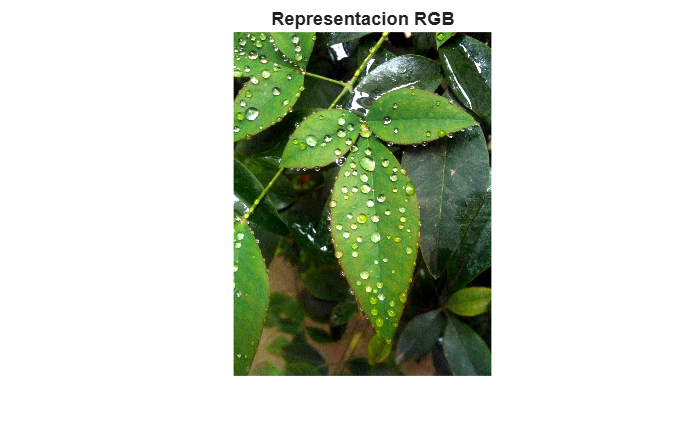

%%1.3 Visualizacion de imagenes
figure('Name', 'Imagen RGB');
imshow(I_rgb);
title('Representacion RGB')

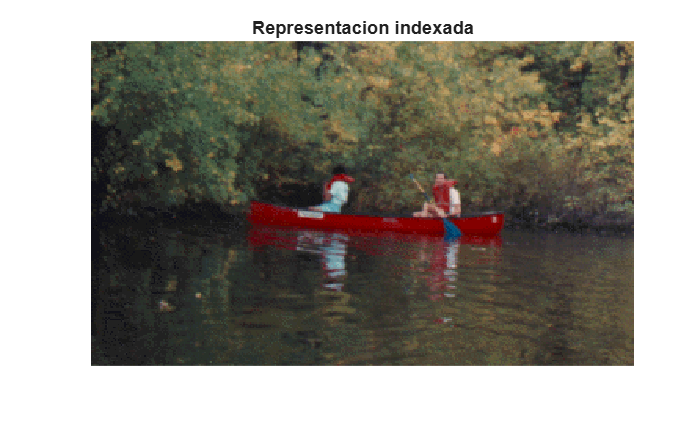


figure('Name', 'Imagen indexada');
imshow(X_ind, map_ind);
title('Representacion indexada')

2. Convierta la imagen indexada anterior a escala de grises y denomine `Igris` a la imagen resultante. Sobre `Igris`:

    2.1 Realice:

- una modificación de **brillo**;

- una modificación de **contraste**.

Muestre `Igris` y las imágenes resultantes, junto con sus histogramas. Indique las transformaciones utilizadas, los intervalos inicial y final y justifique, a partir de ellas y de los histogramas, por qué en un caso se modifica el brillo y en el otro el contraste.

    2.2 Umbralice `Igris` utilizando `imbinarize`. Muestre la imagen binaria y su histograma. Pruebe con diferentes umbrales y observe la relación del valor del umbral con las imágenes resultantes.

    2.3 Obtenga el negativo de `Igris`. Muestre conjuntamente la imagen original y el negativo, así como sus histogramas. Explique la relación entre ambos histogramas.

%% 2. Procesamiento de escala de grises

%Conversion a escala de grises
Igris = ind2gray(X_ind, map_ind);

%% 2.1 Modificacion de brillo y constraste

% Sumamos/restamos una constante k. Al ser uint8, usamos imadd o suma
% saturada.
k_brillo = 40;
I_brillo = imadd(Igris, k_brillo);
% Modificacion de contraste
rango_in = stretchlim(Igris);
I_contraste = imadjust(Igris, rango_in, [0,1]);
% Visualizacion
figure('Name', '2.1 Brillo y Contraste con Histogramas');
t = tiledlayout(2,3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(Igris); title('Igris (Original)');
nexttile; imshow(I_brillo); title(['Brillo (+', num2str(k_brillo), ')']);
nexttile; imshow(I_contraste); title('Contraste Ajustado');

ax1 = nexttile; imhist(Igris); title(ax1, 'Histograma Igris');

ax2 = nexttile; imhist(I_brillo); title(ax2, 'Histograma Brillo');

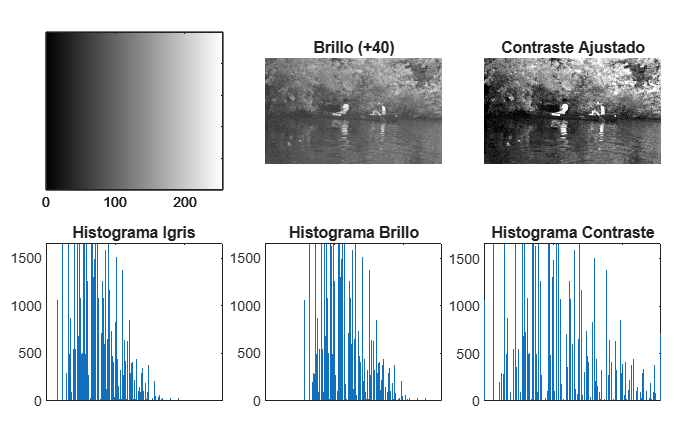

ax3 = nexttile; imhist(I_contraste); title(ax3, 'Histograma Contraste');


%% 2.2 Umbralizacion con imbinarize

T_otsu = graythresh(Igris);
I_bin_otsu = imbinarize(Igris, T_otsu);

T_bajo = 0.3;
T_alto = 0.7;
I_bin_bajo = imbinarize(Igris, T_bajo);
I_bin_alto = imbinarize(Igris, T_alto);

% Visualizacion
figure('Name', '2.2 Umbralización con imbinarize');
t2 = tiledlayout(2,4, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(Igris); title('Igris Original');
nexttile; imshow(I_bin_bajo); title(['Umbral Bajo T = ', num2str(T_bajo)]);
nexttile; imshow(I_bin_otsu); title(['Otsu T = ', num2str(round(T_otsu,2))]);
nexttile; imshow(I_bin_alto); title(['Umbral Alto T = ', num2str(T_alto)]);

ax4 = nexttile; imhist(Igris); title(ax4, 'Histograma Igris');

ax5 = nexttile; imhist(I_bin_bajo); title(ax5, 'Binaria (Bajo)');

ax6 = nexttile; imhist(I_bin_otsu); title(ax6, 'Binaria (Otsu)');

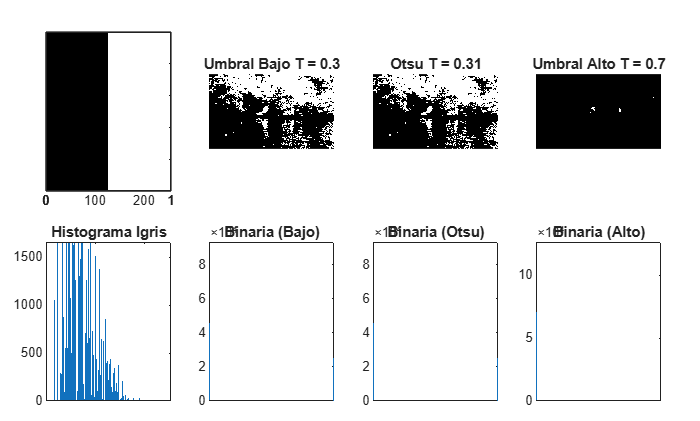

ax7 = nexttile; imhist(I_bin_alto); title(ax7, 'Binaria (Alto)');


%% 2.3 Negativo de Igris

I_neg = imcomplement(Igris);

% Visualización de Igris y negativo
figure('Name', '2.3 Negativo de Igris');
t3 = tiledlayout(2,2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(Igris); title('Igris (Original)');
nexttile; imshow(I_neg); title('Negativo (imcomplement)');

ax8 = nexttile; imhist(Igris); title(ax8, 'Histograma Original');

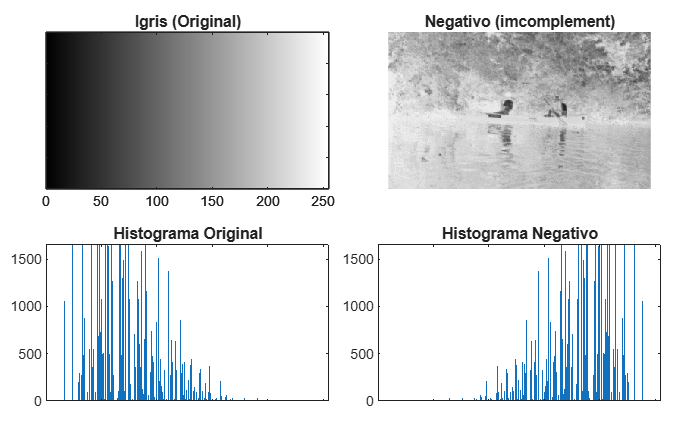

ax9 = nexttile; imhist(I_neg); title(ax9, 'Histograma Negativo');

3. Sobre la imagen "avion1.jpg":

    3.1 Realice una corrección gamma. Pruebe con distintos valores de gamma (al menos un valor de gamma < 1 y otro > 1) y analice el efecto de cada uno sobre la imagen de salida.

    3.2 Ecualice el histograma de la imagen utilizando `histeq` con 256, 64 y 8 niveles de salida. Muestre conjuntamente la imagen original y las tres imágenes obtenidas, junto con sus histogramas. Compare los resultados y explique cómo influye el número de niveles utilizado en la ecualización.

%% 3. Procesamiento sobre "avion1.jpg": Corrección Gamma y Ecualización
clearvars -except I_rgb X_ind map_ind Igris;

% Carga y verificación de la imagen de entrada
I_avion = imread('avion1.jpg');

% Si la imagen fuera RGB, la convertimos a escala de grises
if size(I_avion, 3) == 3
    I_avion = rgb2gray(I_avion);
end

%% 3.1 Corrección Gamma
% La función imadjust(I, [], [], gamma) aplica la transformación gamma s = c * r^gamma
gamma_baja = 0.4; % Gamma < 1 (Aumenta brillo en tonos oscuros y medios)
gamma_alta = 2.2; % Gamma > 1 (Oscurece la imagen, comprime tonos oscuros)

I_gamma_baja = imadjust(I_avion, [], [], gamma_baja);
I_gamma_alta = imadjust(I_avion, [], [], gamma_alta);

% Visualización de Corrección Gamma e Histogramas
figure('Name', '3.1 Corrección Gamma');
tiledlayout(2,3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_avion); title('Original (avion1)');
nexttile; imshow(I_gamma_baja); title(['Gamma = ', num2str(gamma_baja), ' (< 1)']);
nexttile; imshow(I_gamma_alta); title(['Gamma = ', num2str(gamma_alta), ' (> 1)']);

nexttile; imhist(I_avion); title('Hist. Original');

nexttile; imhist(I_gamma_baja); title(['Hist. Gamma ', num2str(gamma_baja)]);

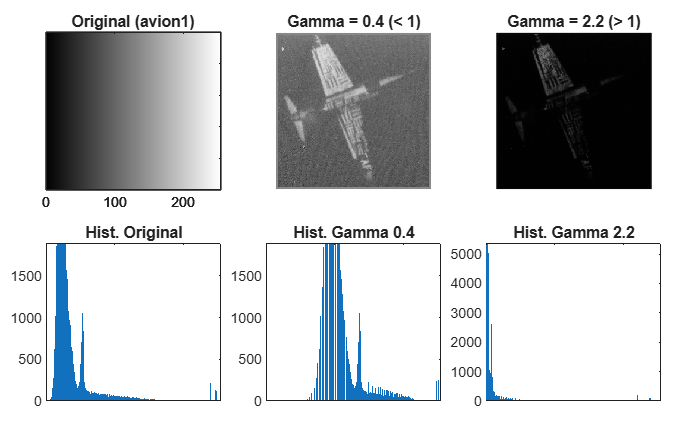

nexttile; imhist(I_gamma_alta); title(['Hist. Gamma ', num2str(gamma_alta)]);


%% 3.2 Ecualización de Histograma con histeq
% Ecualización fijando el número de niveles de salida (n = 256, 64 y 8)
I_eq256 = histeq(I_avion, 256);
I_eq64  = histeq(I_avion, 64);
I_eq8   = histeq(I_avion, 8);

% Visualización de Ecualización e Histogramas
figure('Name', '3.2 Ecualización de Histograma (histeq)');
tiledlayout(2,4, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_avion); title('Original');
nexttile; imshow(I_eq256); title('Ecualizada (256 niv)');
nexttile; imshow(I_eq64);  title('Ecualizada (64 niv)');
nexttile; imshow(I_eq8);   title('Ecualizada (8 niv)');

nexttile; imhist(I_avion); title('Hist. Original');

nexttile; imhist(I_eq256); title('Hist. 256 niveles');

nexttile; imhist(I_eq64);  title('Hist. 64 niveles');

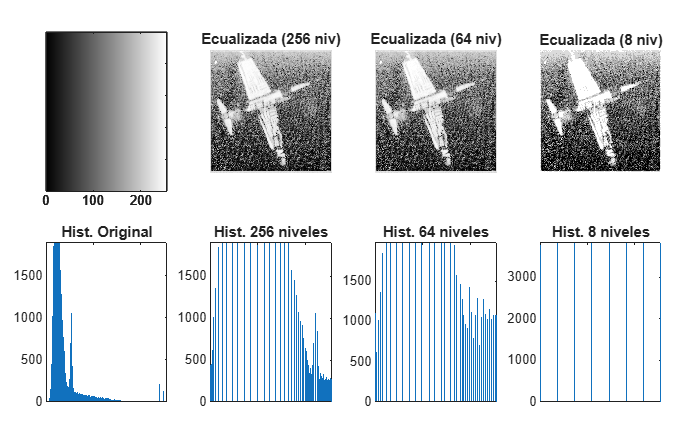

nexttile; imhist(I_eq8);   title('Hist. 8 niveles');

4. Sobre la imagen "matricula.jpg":

    4.1 Averigüe sus dimensiones (filas x columnas) en píxeles. Obtenga una nueva imagen con la mitad de filas y la mitad de columnas y verifique su tamaño. Visualice ambas figuras. Para poder ver el cambio de tamaño puede utilizar la instrucción *truesize *después de *imshow *para que las imágenes no ajusten su tamaño al de la ventana.

    4.2 Rote la imagen un ángulo de 65,3º utilizando los métodos de interpolación `nearest` y `bicubic`. Muestre la imagen original y ambos resultados conjuntamente. Amplíe una zona con bordes o detalles finos para hacer visibles las diferencias entre los dos métodos y explíquelas.

%% 4. Transformaciones geométricas sobre "matricula.jpg"
clearvars -except I_rgb X_ind map_ind Igris I_avion;

% Carga de la imagen matricula.jpg
I_mat = imread('matricula.jpg');

% Si la imagen es RGB, la convertimos a escala de grises
if size(I_mat, 3) == 3
    I_mat = rgb2gray(I_mat);
end

%% 4.1 Dimensiones y Redimensionado 
% Averiguar dimensiones originales
[filas_orig, col_orig] = size(I_mat);
disp('--- Dimensiones de matricula.jpg ---');

--- Dimensiones de matricula.jpg ---


disp(['Original: ', num2str(filas_orig), ' filas x ', num2str(col_orig), ' columnas']);

Original: 187 filas x 500 columnas



% Obtener una nueva imagen con la mitad de filas y columnas (escala 0.5)
I_mitad = imresize(I_mat, 0.5);

% Verificar tamaño de la nueva imagen
[filas_sub, col_sub] = size(I_mitad);
disp(['Reducida: ', num2str(filas_sub), ' filas x ', num2str(col_sub), ' columnas']);

Reducida: 94 filas x 250 columnas


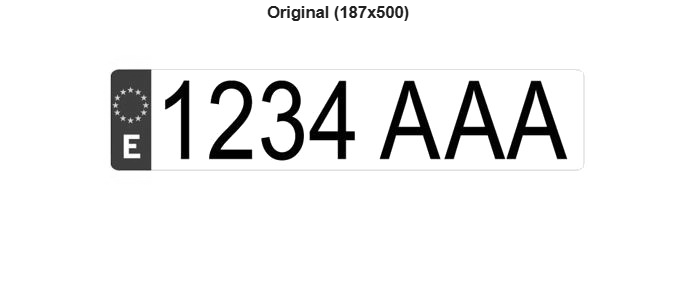


% Visualización con truesize en figuras independientes (para apreciar la diferencia de escala real)
figure('Name', '4.1 Imagen Original (Escala 1:1)');
imshow(I_mat);
truesize; % Fuerza a mostrar 1 píxel de pantalla por píxel de la imagen
title(['Original (', num2str(filas_orig), 'x', num2str(col_orig), ')']);

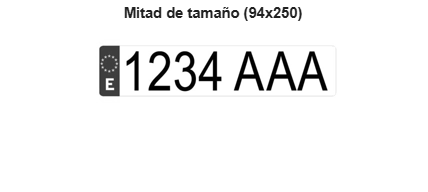


figure('Name', '4.1 Imagen Reducida a la Mitad (Escala 1:1)');
imshow(I_mitad);
truesize;
title(['Mitad de tamaño (', num2str(filas_sub), 'x', num2str(col_sub), ')']);

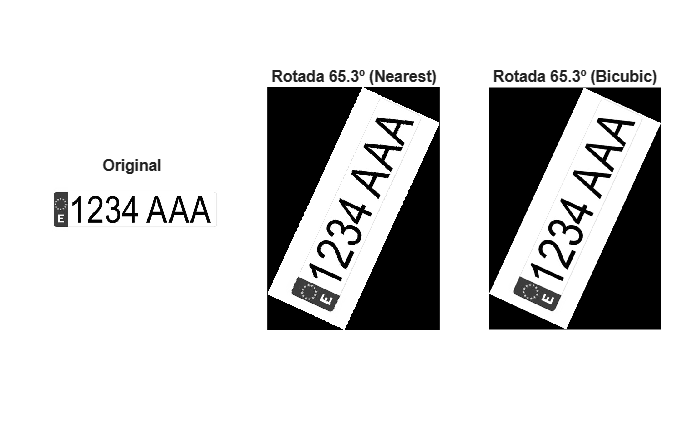



%% 4.2 Rotación de 65.3º e Interpolación 
angulo = 65.3;

% Rotación con interpolación por el vecino más cercano 
I_rot_near = imrotate(I_mat, angulo, 'nearest', 'loose');

% Rotación con interpolación bicúbica 
I_rot_bicubic = imrotate(I_mat, angulo, 'bicubic', 'loose');

% Visualización conjunta
figure('Name', '4.2 Rotación de 65.3º e Interpolación');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_mat); title('Original');
nexttile; imshow(I_rot_near); title(['Rotada ', num2str(angulo), 'º (Nearest)']);
nexttile; imshow(I_rot_bicubic); title(['Rotada ', num2str(angulo), 'º (Bicubic)']);

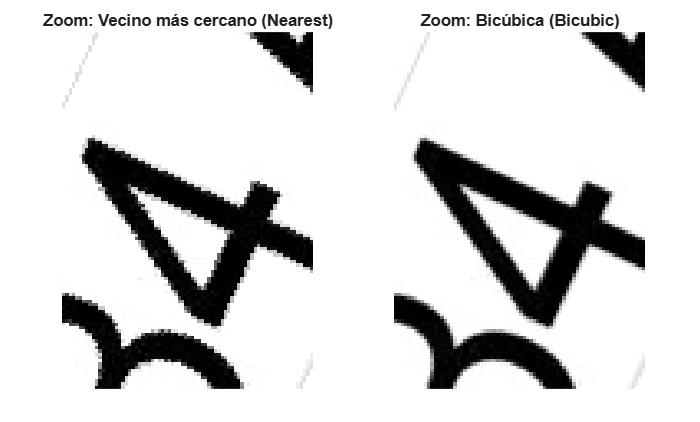


%% 4.2 Visualización ampliada (Zoom) para comparar métodos de interpolación
% Seleccionar una Región de Interés (ROI) sobre los caracteres/bordes de la matrícula
% Definimos una ventana de recorte [filas, columnas] sobre la imagen rotada
[h_r, w_r] = size(I_rot_near);
rango_y = round(h_r*0.4) : round(h_r*0.6); % Zona central vertical
rango_x = round(w_r*0.4) : round(w_r*0.6); % Zona central horizontal

crop_near    = I_rot_near(rango_y, rango_x);
crop_bicubic = I_rot_bicubic(rango_y, rango_x);

figure('Name', '4.2 Zoom en Detalle Fino (Nearest vs Bicubic)');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(crop_near); title('Zoom: Vecino más cercano (Nearest)');
nexttile; imshow(crop_bicubic); title('Zoom: Bicúbica (Bicubic)');

5. Ruido y filtrado

5.1. A partir de la imagen `cell.tif`, obtenga y muestre una versión con ruido gaussiano de media cero y varianza 0,01, que denominaremos `Ig`. Fíltrela utilizando un filtro de promedio del entorno de vecindad, primero con un entorno de 3x3 y después con uno de 5x5. Muestre conjuntamente la imagen original, la imagen ruidosa y las dos imágenes filtradas, utilizando `subplot` o `tiledlayout`/`nexttile`. Compare los resultados y justifique el efecto que tiene el tamaño del entorno sobre la reducción de ruido y la conservación de los detalles de la imagen.

5.2. Obtenga una versión de `cell.tif` con ruido de tipo sal y pimienta de densidad 5 %. Fíltrela utilizando un filtro de mediana y un filtro paso bajo de promedio del entorno de vecindad con entorno 3x3. Muestre conjuntamente la imagen original, la imagen ruidosa y las dos imágenes filtradas. Compare los resultados y responda: ¿qué tipo de filtrado resulta más adecuado para este tipo de ruido? Justifique sus conclusiones teniendo en cuenta tanto la eliminación del ruido como la conservación de bordes y detalles.

5.3. Obtenga y muestre una versión de `cell.tif` con ruido multiplicativo de tipo *speckle *con varianza 0.05. Fíltrela utilizando un filtro de Wiener y un filtro paso bajo de promedio  del entorno de vecindad con entorno 5x5. Muestre conjuntamente la imagen original, la imagen ruidosa y las dos imágenes filtradas. Compare los resultados y responda: ¿cuál de los dos filtros resulta más adecuado para este tipo de ruido? Justifique su respuesta teniendo en cuenta la reducción del ruido y la conservación de los detalles de la imagen.

5.4. Mediante un bucle `for`, obtenga 32 imágenes diferentes a partir de `cell.tif`, añadiendo a cada una ruido gaussiano independiente de media cero y varianza 0,05. Guarde las imágenes utilizando `imwrite` en ficheros con nombres consecutivos (`ruidosa1.bmp`, …, `ruidosa32.bmp`). Puede generar los nombres de los ficheros dentro del bucle *for* utilizando, por ejemplo: "ruidosa" + i + ".bmp".

A continuación, aplique la técnica de promediado de imágenes, utilizando primero 4 imágenes ruidosas, después 8, 16 y, finalmente, las 32 imágenes. Muestre conjuntamente la imagen original, una de las imágenes ruidosas y los resultados obtenidos al promediar 4, 8, 16 y 32 imágenes. Compare visualmente los resultados y explique cómo evoluciona el ruido de la imagen de salida al aumentar el número de imágenes promediadas. Preste especial atención al tipo de datos utilizado durante el cálculo del promedio, para evitar pérdidas de precisión o saturaciones.

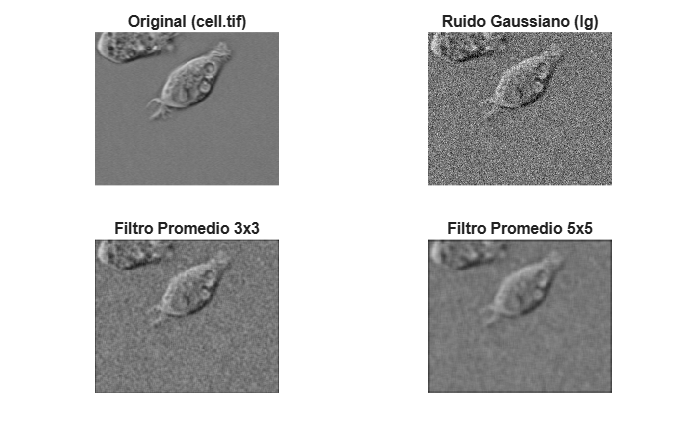

%% 5. Ruido y Filtrado Espacial sobre "cell.tif"
clearvars -except I_rgb X_ind map_ind Igris I_avion I_mat;

% Carga de la imagen original cell.tif
I_cell = imread('cell.tif');
if size(I_cell, 3) == 3
    I_cell = rgb2gray(I_cell);
end

%% 5.1 Ruido Gaussiano y Filtro de Promedio (3x3 vs 5x5)
% Generación de ruido gaussiano: media = 0, varianza = 0.01
Ig = imnoise(I_cell, 'gaussian', 0, 0.01);

% Filtros de promedio (media) mediante fspecial e imfilter
h_prom3 = fspecial('average', [3 3]);
h_prom5 = fspecial('average', [5 5]);

I_prom3 = imfilter(Ig, h_prom3);
I_prom5 = imfilter(Ig, h_prom5);

% Visualización conjunta
figure('Name', '5.1 Ruido Gaussiano y Filtro Promedio');
tiledlayout(2,2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_cell);  title('Original (cell.tif)');
nexttile; imshow(Ig);      title('Ruido Gaussiano (Ig)');
nexttile; imshow(I_prom3); title('Filtro Promedio 3x3');
nexttile; imshow(I_prom5); title('Filtro Promedio 5x5');

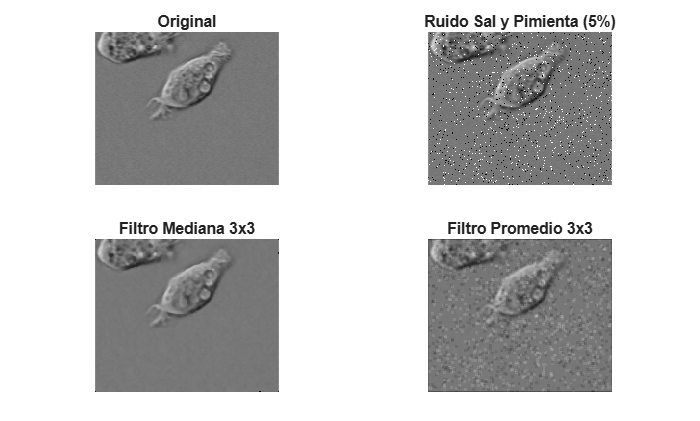



%% 5.2 Ruido Sal y Pimienta: Filtro Mediana vs Promedio 3x3
% Ruido sal y pimienta con densidad del 5% (0.05)
I_sp = imnoise(I_cell, 'salt & pepper', 0.05);

% Filtrado por mediana (3x3) y filtro promedio paso bajo (3x3)
I_med3  = medfilt2(I_sp, [3 3]);
I_sp_prom3 = imfilter(I_sp, h_prom3);

% Visualización conjunta
figure('Name', '5.2 Ruido Sal y Pimienta: Mediana vs Promedio');
tiledlayout(2,2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_cell);     title('Original');
nexttile; imshow(I_sp);       title('Ruido Sal y Pimienta (5%)');
nexttile; imshow(I_med3);     title('Filtro Mediana 3x3');
nexttile; imshow(I_sp_prom3); title('Filtro Promedio 3x3');

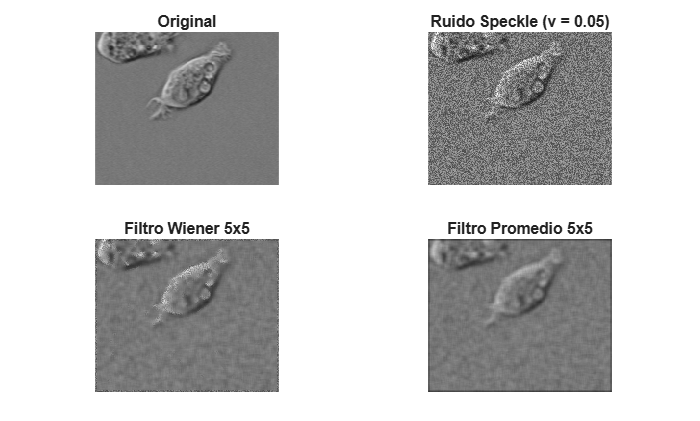



%% 5.3 Ruido Speckle: Filtro Wiener vs Promedio 5x5
% Ruido multiplicativo de tipo speckle con varianza 0.05
I_speckle = imnoise(I_cell, 'speckle', 0.05);

% Filtrado mediante Wiener (5x5) y Promedio 5x5
I_wiener5 = wiener2(I_speckle, [5 5]);
I_spk_prom5 = imfilter(I_speckle, h_prom5);

% Visualización conjunta
figure('Name', '5.3 Ruido Speckle: Wiener vs Promedio');
tiledlayout(2,2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_cell);       title('Original');
nexttile; imshow(I_speckle);   title('Ruido Speckle (v = 0.05)');
nexttile; imshow(I_wiener5);   title('Filtro Wiener 5x5');
nexttile; imshow(I_spk_prom5); title('Filtro Promedio 5x5');

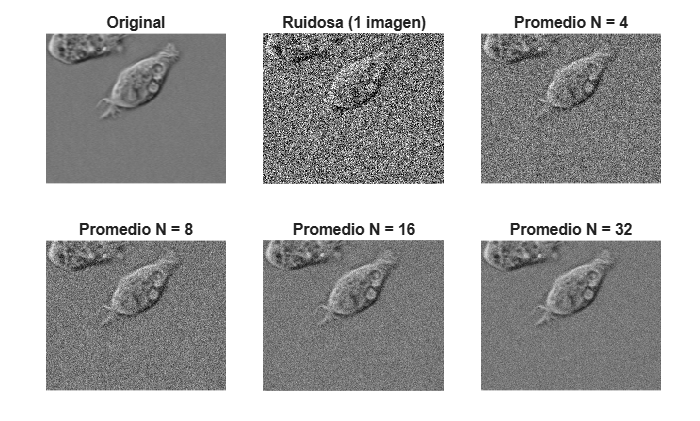



%% 5.4 Generación de 32 imágenes ruidosas y Promediado
% Conversión a double para operaciones aritméticas de suma/promedio sin saturación
I_cell_dbl = im2double(I_cell);

% Bucle for para generar y guardar 32 imágenes con ruido gaussiano (m = 0, var = 0.05)
for i = 1:32
    % Generación de ruido gaussiano independiente
    I_ruidosa = imnoise(I_cell, 'gaussian', 0, 0.05);
    
    % Guardar en fichero con nombre ruidosa1.bmp, ..., ruidosa32.bmp
    nombre_archivo = "ruidosa" + i + ".bmp";
    imwrite(I_ruidosa, nombre_archivo);
end

% Carga y promediado usando precisión de punto flotante (double)
acumulador = zeros(size(I_cell_dbl));

% Variables para almacenar las imágenes promediadas
for i = 1:32
    img_i = im2double(imread("ruidosa" + i + ".bmp"));
    acumulador = acumulador + img_i;
    
    if i == 4
        I_prom4 = acumulador / 4;
    elseif i == 8
        I_prom8 = acumulador / 8;
    elseif i == 16
        I_prom16 = acumulador / 16;
    elseif i == 32
        I_prom32 = acumulador / 32;
    end
end

% Visualización del Promediado
figure('Name', '5.4 Promediado de N Imágenes Ruidosas');
tiledlayout(2,3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_cell);                  title('Original');
nexttile; imshow(imread("ruidosa1.bmp"));   title('Ruidosa (1 imagen)');
nexttile; imshow(I_prom4);                 title('Promedio N = 4');
nexttile; imshow(I_prom8);                 title('Promedio N = 8');
nexttile; imshow(I_prom16);                title('Promedio N = 16');
nexttile; imshow(I_prom32);                title('Promedio N = 32');